# **Validation of resonant frequency equation**

**2023-06-02 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

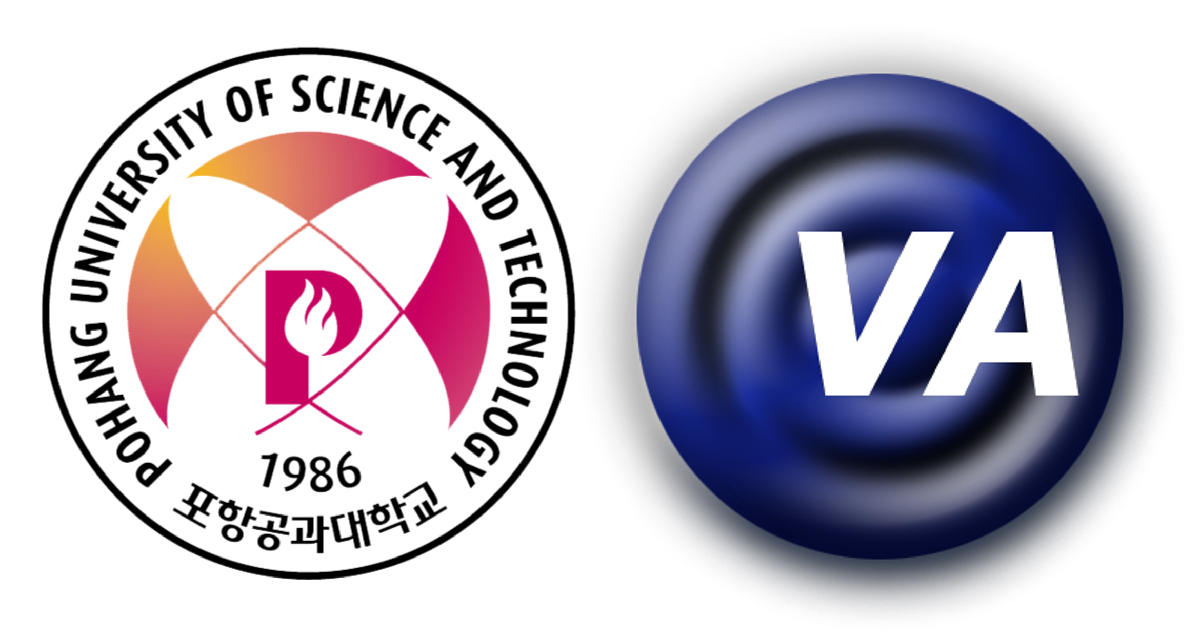

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear
syms theta1 theta4

% Define the simulation frequency
f = 75e3;

% Load the material properties
mat = import_material('materials_OBS.txt');

% Initialize the symbols for material properties and design parameters of elements
r1 = 7e-3;
r2 = 7e-3;
r3 = 7e-3;
r4 = 1e-3;

Z1 = mat("Stainless Steel",:).rho*mat("Stainless Steel",:).v3*pi*r1^2;
Z2 = mat("C-21",:).rho*mat("C-21",:).v3*pi*r2^2;
Z3 = mat("Aluminum",:).rho*mat("Aluminum",:).v3*pi*r3^2;
Z4 = @(r4) mat("Aluminum",:).rho*mat("Aluminum",:).v3*pi*r4^2;

c1 = mat("Stainless Steel",:).v3;
c2 = mat("C-21",:).v3;
c3 = mat("Aluminum",:).v3;
c4 = mat("Aluminum",:).v3;

theta = @(l,c) 2*pi*f/c*l;

l21 = 2e-3;
% l21 = linspace(0,4e-3,9);
l22 = 4e-3-l21;
% l3 = 2e-3;
l3 = linspace(1e-3,20e-3,100);

[L21,L3] = meshgrid(l21,l3);

L21 = reshape(L21,[],1);
L22 = 4e-3-L21;
L3 = reshape(L3,[],1);

l1 = zeros(length(l21),length(l3));
l4 = zeros(length(l21),length(l3));

for i = 1:length(l21)
    for j = 1:length(l3)
        eqn1 = Z1/Z2*tan(theta(l21(i),c2))*tan(theta1) == 1;
        eqn2 = Z3/Z2*tan(theta(l22(i),c2))*tan(theta(l3(j),c3)) + Z4(r4)/Z3*tan(theta(l3(j),c3))*tan(theta4) + Z4(r4)/Z2*tan(theta4)*tan(theta(l22(i),c2)) == 1;
        theta1_ = double(vpasolve(eqn1,theta1,[0 pi/2]));
        theta4_ = double(vpasolve(eqn2,theta4,[0 pi/2]));
        if(isempty(theta1_))
            l1(i,j) = c1/(4*f);
        else
            l1(i,j) = theta1_*c1/(2*pi*f);
        end
        if(isempty(theta4_))
            l4(i,j) = 0;
        else
            l4(i,j) = theta4_*c4/(2*pi*f);
        end
    end
end

L1 = reshape(l1',[],1);
L4 = reshape(l4,[],1);

eqn1_chk = @(l1, l2) Z1/Z2.*tan(theta(l2,c2)).*tan(theta(l1,c1));
eqn2_chk = @(l2, l3, l4) Z3./Z2.*tan(theta(l2,c2)).*tan(theta(l3,c3)) + ...
    Z4(r4)./Z3.*tan(theta(l3,c3)).*tan(theta(l4,c4)) + ...
    Z4(r4)./Z2.*tan(theta(l4,c4)).*tan(theta(l2,c2));

param = [L1 L21 L22 L3 L4];

param_chk(:,1) = eqn1_chk(param(:,1),param(:,2));
param_chk(:,2) = eqn2_chk(param(:,3),param(:,4),param(:,5));

param_chk_ind1 = find(param_chk(:,1)>=0.99 & param_chk(:,1)<=1.01);
param_chk_ind2 = find(param_chk(:,2)>=0.99 & param_chk(:,2)<=1.01);

param = param(param_chk_ind2,:);

for i=1:length(param)
    fid = fopen(['parameters\resonant_freq_eq_proof\parameters_1234_RFE_' num2str(i) '.txt'],'wt');
    fprintf(fid, "Element,Length,Radius,Material\n");
    fprintf(fid, "1,m,m,1,1\n");
    fprintf(fid, "1,%e,%e,Stainless Steel,1\n", param(i,1),r1);
    fprintf(fid, "2,%e,%e,C-21,4\n", param(i,2)+param(i,3),r2);
    fprintf(fid, "3,%e,%e,Aluminum,1\n", param(i,4),r3);
    fprintf(fid, "4,%e,%e,Aluminum,1\n", param(i,5),r4);
    fclose(fid);
end